# Analysis of Robust Stability (RS) and Robust Performance (RP)

load statespace_data A B C D FWT

% 2 inputs, 2 outputs
s = tf('s');
G = FWT(1:2, 1:2);

% performance weights
wp = [(s/3+0.3*2*pi)/(s+pi*6e-5) 0;
    0 0.05];

wu = [0.005 0;
       0 (0.005*s^2 + 0.0007*s+0.00005)/(s^2 + 0.0014*s + 10^(-6))];

% uncertainty weights
wi1 = ((1/16*pi)*s + 0.3)/((1/64*pi)*s + 1);
wi2 = wi1;

wo1 = (0.05*s + 0.25)/(0.01*s + 1);
wo2 = wo1;

wi = [wi1 0;
      0 wi2];
wo = [wo1 0;
     0 wo2];

## 3. Frequency response of weights

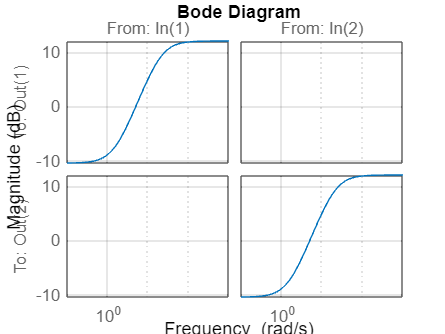

% frequency response of uncertainty weights
figure
bodemag(wi)
grid on

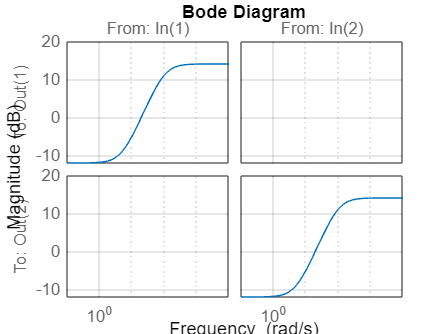


figure
bodemag(wo)
grid on


% uncertain TF singular values 

pb1 = ultidyn("idelta", 2)

pb1 =   Uncertain LTI dynamics "idelta" with 2 outputs, 2 inputs, and gain less than 1.


pb2 = ultidyn("odelta", 2)

pb2 =   Uncertain LTI dynamics "odelta" with 2 outputs, 2 inputs, and gain less than 1.



wid = wi*idelta;
wod = wo*odelta;

X = wid*G*wod;

X =
 
  A = 
                            ?             ?
   ?                   -20.37             0
   ?                        0        -20.37
   Omega (rad/s             0             0
   z1dot (m/s)              0             0
   z1 (m)                   0             0
   z2dot (m/s)              0             0
   z2 (m)                   0             0
   ?                        0             0
   ?                        0             0
 
                 Omega (rad/s   z1dot (m/s)
   ?                        8             0
   ?                        0             0
   Omega (rad/s        -0.422       -0.2204
   z1dot (m/s)        0.02328      -0.01085
   z1 (m)                   0             1
   z2dot (m/s)         0.1455      -0.05984
   z2 (m)                   0             0
   ?                        0             0
   ?                        0             0
 
                       z1 (m)   z2dot (m/s)
   ?                        0             0
   ?           

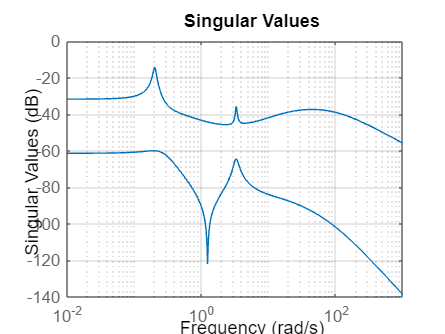


figure
sigma(X)
grid on

## 4. Augmented Generalised Plant

% Define plant and in- and outputs
G.u = 'udu';
G.y = 'y';

wp.u = 'v';
wp.y = 'z1';

wu.u = 'u';
wu.y = 'z2';

wo.u = 'y';
wo.y = 'do';

wi.u = 'u';
wi.y = 'di';

% Build system
sumblock1 = sumblk("ydy = y + dy", 2);
sumblock2 = sumblk("udu = u + du", 2);
sumblock3 = sumblk("v = w + ydy", 2);

P = connect(G, wu, wp, wo, wi, sumblock1, sumblock2, sumblock3, {'w', 'u', 'du', 'du'}, {'z1', 'z2', 'v', 'do', 'di'});

## 5. Checking NS, NP, RS, RP

load mixedsensitivitycontroller.mat MS_C

% generalised Nyquist
ol = MS_C*P;

Error using  * 
Model I/O
dimensions
must
agree.

tdet = eye(2) - ol;

det = tdet(1,1)*tdet(2,2) - tdet(1,2)*tdet(2,1);

nyquist(det);
title('Nyquist of Determinant')